close all
clear all
clc
plot_counter=1;
Question_mark='Q24 ';

run('BASIC.m')
n = length(A)-1;
m = length(B)-1;
d0 = n-m;
d = 2*d0+4;

T_s=0.3;
tfinal=100;
freq=5;
variance=0.01;
C=0;
[uc,t,Status,tfinal,Noix]=Datagen(1,T_s,tfinal,freq,variance,C);
Titlework=[Question_mark,Status];
uc(1:40,1)=ones(40,1);

Q = poly(zeros(1,d+n-1));
[F,G] = dab(A,1,Q);

Q = poly(zeros(1,n-1));
BF = conv(B,F);
[R,R_bar] = dab(Q,1,BF);

N=numel(t);
u=zeros(1,N);
y=zeros(1,N);
var_y=zeros(1,N);  mean_y=zeros(1,N); ACLS_y=zeros(1,N);
var_u=zeros(1,N);  mean_u=zeros(1,N); ACLS_u=zeros(1,N);
Normerror=0;
Error=0;

for i=d+n+d0:N-d
    y(i) = -A(2:end)*y(i-1:-1:i-n)' + B*u(i-d0:-1:i-m-d0)';    
    u(i) = (uc(i+d) -G*y(i:-1:i-length(G)+1)'-R_bar*u(i-1:-1:i-length(R_bar))')./sum(R);
    var_u (i)=var(u)    ;mean_u(i)=mean(u)  ;ACLS_u(i)=u(i)^2+ACLS_u(i-1)   ;
    var_y(i)=var(y)     ;mean_y(i)=mean(y)  ;ACLS_y(i)=y(i)^2+ACLS_y(i-1)   ;
    Error=(y(i)-uc(i))^2+Error;
    Normerror=norm(Error,2)+Normerror;
end

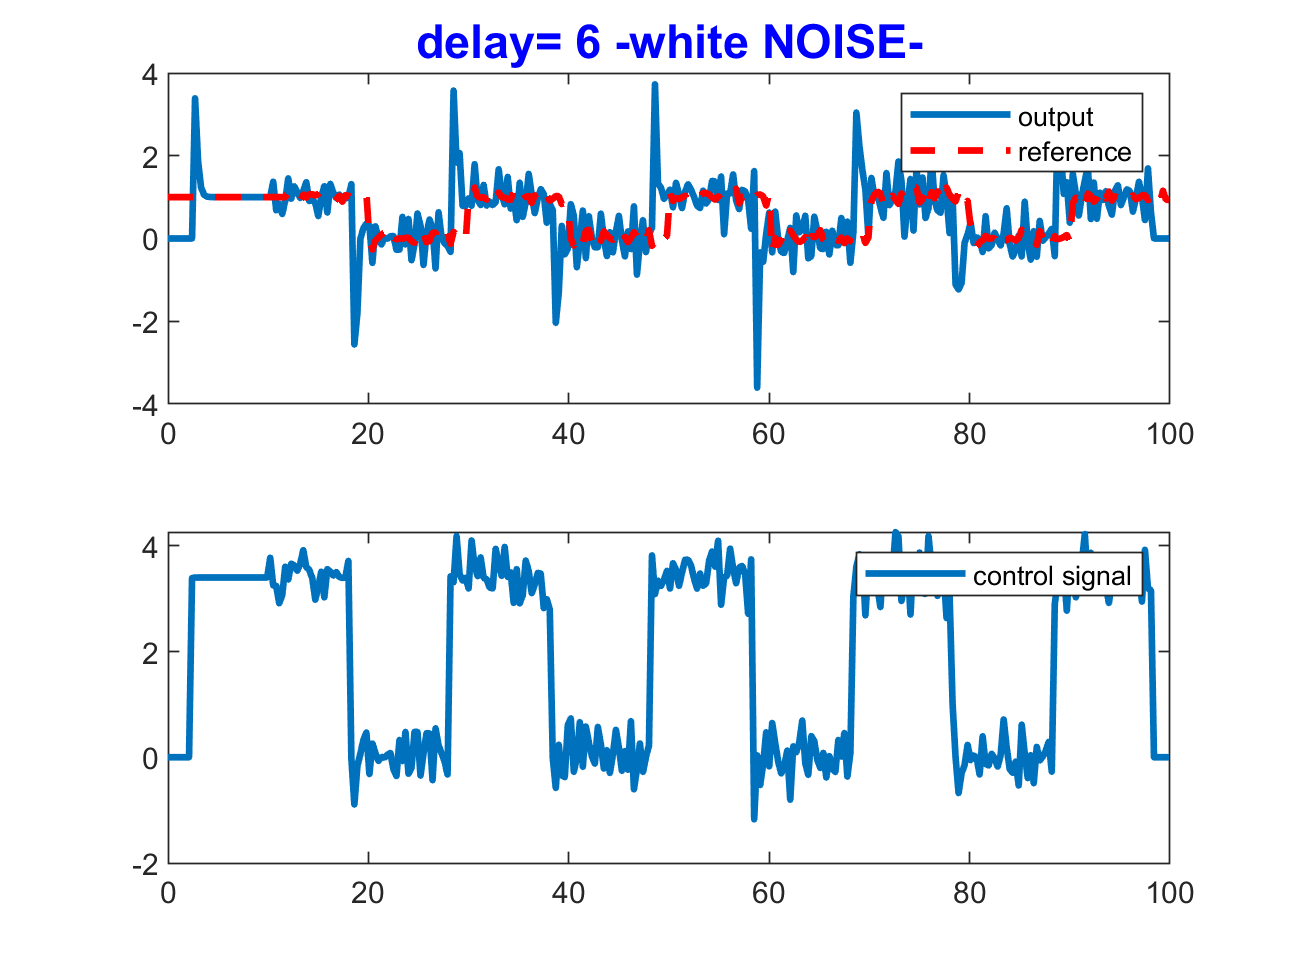

figure(2);
subplot(2,1,1);
    plot(t,y,t,uc','--r','linewidth',2);
    title(['delay= ',int2str(d) ,' ' Status],'Color','b','fontsize',14)
    legend('output','reference');

subplot(212);
    plot(t,u,'linewidth',2);
    legend('control signal');
print(gcf,[Titlework , ' d=' num2str(d) ' Result.png'],'-dpng','-r400');

% plot_counter=plot_counter+1;

disp(['mean of u=',num2str(mean_u(end-d)),'   mean of y=',num2str(mean_y(end-d))])

mean of u=1.9198   mean of y=0.57245


disp(['Error of u=',num2str(Error),'   NormError of y=',num2str(Normerror)])    

Error of u=202.6077   NormError of y=31932.46
